function X=DTFT(x, n0, dw)
    N = length(x);
    
    w = (-pi: dw: pi);
    len = length(w);
    X = zeros(1, len);
        
    for k = 1:len
        for n = 1:N
            X(k) = X(k)+x(n)*exp(-1j*w(k)*(n+n0-1));
        end
    end

end

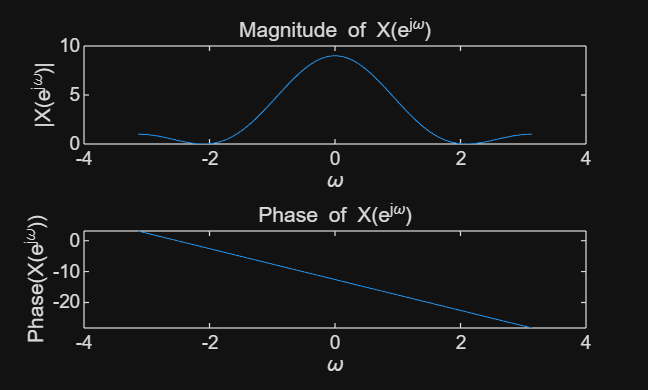

% 定义信号 x[n] 和参数 n0 和 dw
x = [1, 2, 3, 2, 1];
n0 = 3;  % 表示 x[3] 对应 n = 0
dw = 0.01;  % 频率采样间隔

% 调用你编写的 DTFT 函数
X = DTFT(x, n0, dw);

% 可视化结果
omega = -pi:dw:pi;  % 定义频率范围
figure;
subplot(2, 1, 1);
plot(omega, abs(X));
title('Magnitude of X(e^{j\omega})');
xlabel('\omega');
ylabel('|X(e^{j\omega})|');

subplot(2, 1, 2);
plot(omega, unwrap(angle(X)));
title('Phase of X(e^{j\omega})');
xlabel('\omega');
ylabel('Phase(X(e^{j\omega}))');